clc, clear, close all

%%%ПАРАМЕТРЫ СИСТЕМЫ:
numSymPerFrame = 2^12;  % Кол-во бит 
M = 16;                 % Глубина модуляции
k = log2(M);
filtlen = numSymPerFrame*2^(0);         % Длина фильтра в символах
rolloff = 0.25;         % Коэффициент сглаживания
sps = 16;               % количества выборок на символ
fss1 = 0.2 * sps;       % Для управления смещением спм сигнала от 0 до 2pi
fss2 = 0.7 * sps; 
EbNoVec = (0:7);       % величина Eb/No (dB)
codeRate = 2/3;         % для кода со скоростью 2/3 с помощью функции poly2trellis. 
counter = 0;            % Счетчик для РУ
traceBack = 16;         % глубина обратного прослеживания для декодера Витерби [бит]. Обычно выбирается 5-10*ограничение кода (=2 из 2/3)

%%ОСШ
snr = EbNoVec + 10*log10((k*codeRate)/sps); %k = BitsPerSymbol; sps = SamplesPerSymbol

        berEst = zeros(size(EbNoVec));
        for n = 1:length(snr)
            % Обнуление ошибок и бит
            numErrs = 0;
            numBits = 0;
        
            while numErrs < 10

        %%ПЕРЕДАТЧИК 1
        
                [txSigUp1,tPoly1,rrcFilter1,ts1,dataIn1] = Transmitter(numSymPerFrame,k,M,rolloff,filtlen,sps,fss1);
        
        %%ПЕРЕДАТЧИК 2
        
                [txSigUp2,tPoly2,rrcFilter2,ts2,dataIn2] = Transmitter(numSymPerFrame,k,M,rolloff,filtlen,sps,fss2);

        %%%КАНАЛ
        
        %%ПРОХРЖДЕНИЕ ЧЕРЕЗ АБГШ
        
                NoiseSig1 = awgn(txSigUp1,snr(n),'measured');
                NoiseSig2 = awgn(txSigUp2,snr(n),'measured'); 
        
                rxSig = NoiseSig1 + NoiseSig2;

        %%ИНТЕРФЕРЕНЦИОННОЕ ВЗАИМОДЕЙСТВИЕ 
                a1 = 1.0; %Весовые коэффициенты гармонических составляющих
                a2 = 0.3;
                a3 = 0.1;

                interfChan = a1*rxSig + a2*rxSig.^2 + a3*rxSig.^3;

        %%ПРИЕМНИК 1
        
                [dataOut1] = Receiver(rrcFilter1,filtlen,sps,fss1,interfChan,ts1,M,k,tPoly1,traceBack);
        
        %%ПРИЕМНИК 2
        
                [dataOut2] = Receiver(rrcFilter2,filtlen,sps,fss2,interfChan,ts2,M,k,tPoly2,traceBack);
        
        %РАССЧЕТ КОЛЛИЧЕСТВА ОШИБОЧНЫХ БИТ 1
        
                decDelay = 2*traceBack; %Задержка декодера [бит]
                if length(dataIn1) > decDelay
                    nErrors = biterr(dataIn1(1:end - decDelay),dataOut1(decDelay + 1:end));
                else
                    nErrors = 0;
                end
                %nErrors = biterr(dataIn1,dataOut1); %Для рассчетов без кодирования
                
                % Счетчики бит и ошибок
                numErrs = numErrs + nErrors;
                numBits = numBits + numSymPerFrame*k;
            end
        
        %%ОЦЕНКА КОЭФФИЦИЕНТА БИТОВЫХ ОШИБОК 1
              
                berEst1(n) = numErrs/numBits

            %РАССЧЕТ КОЛЛИЧЕСТВА ОШИБОЧНЫХ БИТ 2
      
              decDelay = 2*traceBack; %Задержка декодера [бит]
              if length(dataIn2) > decDelay
                  nErrors = biterr(dataIn2(1:end - decDelay),dataOut2(decDelay + 1:end));
              else
                  nErrors = 0;
              end
              % Счетчики бит и ошибок
              numErrs = numErrs + nErrors;
              numBits = numBits + numSymPerFrame;
      
      %%ОЦЕНКА КОЭФФИЦИЕНТА БИТОВЫХ ОШИБОК 2
      
            berEst2(n) = numErrs/numBits;
        end

berEst1 = 0.1226

berEst1 =     0.1226    0.1212


berEst1 =     0.1226    0.1212    0.1187


berEst1 =     0.1226    0.1212    0.1187    0.1102


berEst1 =     0.1226    0.1212    0.1187    0.1102    0.1003


berEst1 =     0.1226    0.1212    0.1187    0.1102    0.1003    0.0660


berEst1 =     0.1226    0.1212    0.1187    0.1102    0.1003    0.0660    0.0344


berEst1 =     0.1226    0.1212    0.1187    0.1102    0.1003    0.0660    0.0344    0.0085


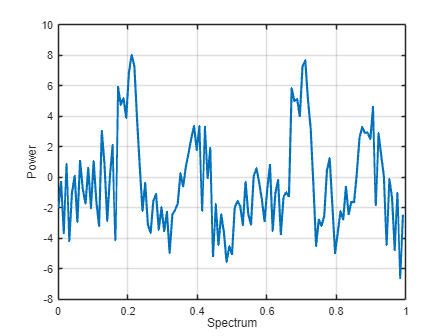

      
        %%ОЦЕНКА СПМ МЕТОДОМ УЭЛЧА
        
        [pxx,wx] = pwelch(interfChan,[],[],128,[]); %Второе значение - размер окна, третье - прекрытие окон, 
                % четвертое - количество ДПФ преобразований (разделений на них), пятое - указание на какой частоте СПМ
        plot(wx,10*log10(pxx),'LineWidth',2)
        grid
        xlabel('Spectrum')
        ylabel('Power')

        
        %%ТЕОРЕТИЧЕСКИЕ ЗНАЧЕНИЯ КБО С АБГШ КАНАЛОМ
        
        berTheoryawgn1 = berawgn(EbNoVec,'qam',M);
        semilogy(EbNoVec,berEst1,'*','LineWidth',3)
        hold on
        berTheoryawgn2 = berawgn(EbNoVec,'qam',M);
        semilogy(EbNoVec,berEst2,'+','LineWidth',4)
        hold on
        semilogy(EbNoVec,berTheoryawgn1,'LineWidth',3)
        hold on
        spect = distspec(tPoly1,8);
        
        %%ТЕОРЕТИЧЕСКИЕ ЗНАЧЕНИЯ КБО С КОДЕРОМ КАНАЛА:
        
        berTheoryCoded = bercoding(EbNoVec,'conv','hard',codeRate,spect,'qam',M,'nondiff')

berTheoryCoded =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.1524


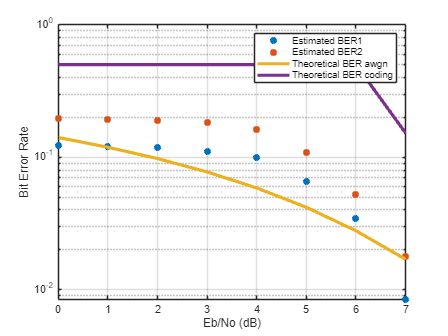

        semilogy(EbNoVec,berTheoryCoded,'LineWidth',3)
        grid
        legend('Estimated BER1','Estimated BER2','Theoretical BER awgn','Theoretical BER coding')
        xlabel('Eb/No (dB)')
        ylabel('Bit Error Rate')

%    end
%end
        
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%ФУНКЦИИ


function [txSigUp,tPoly,rrcFilter,ts,dataIn] = Transmitter(numSymPerFrame,k,M,rolloff,filtlen,sps,fss)
%%ПЕРЕДАТЧИК

%ГЕНЕРАЦИЯ ВХОДНЫХ ДАННЫХ
        rng default
        dataIn = randi([0 1],numSymPerFrame,1);

%%ПРИМЕНЕНИЕ СВЕРТОЧНОГО КОДА:

            constrlen = [5 4];           % Длина кодового ограничения
            genpoly = [23 35 0; 0 5 13]; % Создание Полиномов
    
            tPoly = poly2trellis(constrlen,genpoly); %Определение решетки сверточного кодирования                                         
        
%%КОДИРОВАНИЕ ВХОДНЫХ ДАННЫХ:

            dataEnc = convenc(dataIn,tPoly);
            dataSym = bit2int(dataEnc,k);
         
%%КАМ 
            txSig = qammod(dataSym,M);


%%СОЗДАНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА: 
        
            rrcFilter = rcosdesign(rolloff,filtlen,sps,"sqrt"); % функция создания фильтра корня прип-ого cos
            txSignal = upfirdn(txSig,rrcFilter,sps,1);
        

%%%ПРОХОЖДЕНИЕ ЧЕРЕЗ СМЕСИТЕЛЬ
   
            ts = (0:length(txSignal)-1)/sps;
            fc = exp(1i * 2 * pi * fss * ts.');           % Частота гетеродина [Гц]
             
            txSigUp = txSignal.*fc; 
        end


function [dataOut] = Receiver(rrcFilter,filtlen,sps,fss,rxSig,ts,M,k,tPoly,traceBack)
%%ПРИЕМНИК

%%СМЕСИТЕЛЬ

        rxSigdown = rxSig .* exp(-1i * 2 * pi * fss * ts.');

%%ФИЛЬТР ПРИПОДНЯТОГО КОСИНУСА
        rxFiltSignal = ...
            upfirdn(rxSigdown,rrcFilter,1,sps);       % Уменьшениче частоты дисркетизации и фильтрация
        rxFiltSignal = ...
            rxFiltSignal(filtlen + 1:end - filtlen); 
     
%ДЕМОДУЛЯТОР КАМ
        rxSym = qamdemod(rxFiltSignal,M);
        rxSym = rxSym(:);
%ПЕРЕВОД СИМВОЛОВ В БИТЫ
        codedDataOut = int2bit(rxSym,k);                     
        numCodeWords = ...
            floor(length(codedDataOut)*2/3); % Количество полных кодовых слов
        dataOut = ...
            vitdec(codedDataOut(1:numCodeWords*3/2), ...
            tPoly,traceBack,'cont','hard');  % Декодирование данных
end



